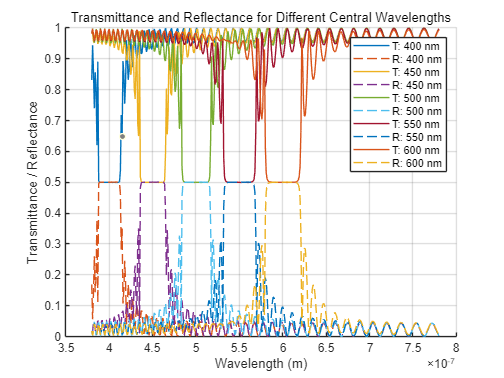

n_e = 1.65;      
n_o = 1.55;   
n_s = 1.3;   

% 중심 파장 (central wavelength) 변화 범위 설정
central_wavelengths = [400, 450, 500, 550, 600] * 10^(-9); % 단위: 미터

figure;
hold on;
grid on;
title('Transmittance and Reflectance for Different Central Wavelengths');
xlabel('Wavelength (m)');
ylabel('Transmittance / Reflectance');

% 중심 파장마다 결과 계산
for lamda_c = central_wavelengths
    p = lamda_c / ((n_o + n_e) / 2); % pitch 계산

    d = 10 * (10^(-6)); % CLC thickness
    N = 1000;           % number of CLC waveplates
    t = d / N;          % thickness of each CLC waveplate

    e_0 = 8.85 * (10^(-12)); % vacuum permittivity
    u = 4 * pi * (10^(-7));  % vacuum magnetic permeability 
    c_light = 3 * (10^(8));  % speed of light in vacuum
    l = d / p;               % thickness (depth) per pitch

    %--------------------------- Memory allocation for plotting -----------------------
    axis_x = zeros(1, 401);
    axis_y = zeros(1, 401); % Transmittance
    axis_a = zeros(1, 401);
    axis_b = zeros(1, 401); % Reflectance
    n = 1;
    m = 1;

    %--------------------------- Wavelength loop ----------------------------
    for lamda = 380 * 10^(-9) : 10^(-9) : 780 * 10^(-9)

        omega = 2 * pi * c_light / lamda;  % angular frequency 
        k_0 = 2 * pi / lamda;             % wave number

        %---------------- Wave vectors for substrates ------------------
        k_1_0 = [0 0 n_s * k_0];      
        k_2_0 = [0 0 -n_s * k_0];
        k_3_0 = [0 0 n_s * k_0];
        k_4_0 = [0 0 -n_s * k_0];

        %---------------- Polarization vectors for substrates ---------------
        p_1_1 = cross(k_1_0, [1 0 0]);                                        
        p_1_0 = p_1_1 / norm(p_1_1);    

        p_1_2 = cross(k_2_0, [1 0 0]);
        p_2_0 = p_1_2 / norm(p_1_2);

        p_1_3 = cross(k_3_0, p_1_0);
        p_3_0 = p_1_3 / norm(p_1_3);

        p_1_4 = cross(k_4_0, p_2_0);
        p_4_0 = p_1_4 / norm(p_1_4);

        %---------------- Polarization vectors of magnetic field --------------
        q_1_0 = cross(k_1_0 / (omega * u), p_1_0);
        q_2_0 = cross(k_2_0 / (omega * u), p_2_0);
        q_3_0 = cross(k_3_0 / (omega * u), p_3_0);
        q_4_0 = cross(k_4_0 / (omega * u), p_4_0);

        %---------------- Components of 4x4 Matrix for substrates --------------
        D_0 =  [p_1_0(1), p_2_0(1), p_3_0(1), p_4_0(1); 
                p_1_0(2), p_2_0(2), p_3_0(2), p_4_0(2);
                q_1_0(1), q_2_0(1), q_3_0(1), q_4_0(1); 
                q_1_0(2), q_2_0(2), q_3_0(2), q_4_0(2)];

        P_0 = diag([exp(1i * n_s * k_0 * t), exp(1i * (-n_s) * k_0 * t), exp(1i * n_s * k_0 * t), exp(1i * (-n_s) * k_0 * t)]);

        %---------------- Initialize transfer matrix --------------------------
        M = diag([1, 1, 1, 1]);

        %---------------- Loop for rotation angle of CLC molecules -------------
        for w = 1:N
            theta = 2 * pi * w * l / N;
            c = [cos(theta), sin(theta), 0]; % molecule director

            %----------- Wave vector propagating in CLCs -----------------------
            g_1 = sqrt(omega^2 * u * e_0 * n_o^2);
            g_2 = -g_1;
            g_3 = sqrt(omega^2 * u * e_0 * n_e^2);
            g_4 = -g_3;

            k_1 = [0 0 g_1];
            k_2 = [0 0 g_2];
            k_3 = [0 0 g_3];
            k_4 = [0 0 g_4];

            %---------------- Polarization vectors ----------------------------
            p_1 = cross(k_1, c) / norm(cross(k_1, c));
            p_2 = cross(k_2, c) / norm(cross(k_2, c));
            p_3 = cross(p_1, k_3) / norm(cross(p_1, k_3));
            p_4 = cross(p_2, k_4) / norm(cross(p_2, k_4));

            %---------------- Polarization vectors of magnetic field -----------
            q_1 = cross(k_1 / (omega * u), p_1);
            q_2 = cross(k_2 / (omega * u), p_2);
            q_3 = cross(k_3 / (omega * u), p_3);
            q_4 = cross(k_4 / (omega * u), p_4);

            %---------------- Components of 4x4 Matrix -------------------------
            D = [p_1(1), p_2(1), p_3(1), p_4(1); 
                 p_1(2), p_2(2), p_3(2), p_4(2);
                 q_1(1), q_2(1), q_3(1), q_4(1); 
                 q_1(2), q_2(2), q_3(2), q_4(2)];

            P = diag([exp(1i * g_1 * t), exp(1i * g_2 * t), exp(1i * g_3 * t), exp(1i * g_4 * t)]);

            M = M * D * P / D;
        end

        M = D_0 \ M * D_0; % Final 4x4 Matrix

        %---------------- Calculation for Transmittance ------------------------
        T_1 = abs(M(1,1)^2 / (M(1,1)*M(3,3) - M(1,3)*M(3,1))^2);
        T_2 = abs(M(3,3)^2 / (M(1,1)*M(3,3) - M(1,3)*M(3,1))^2);
        T_3 = abs(M(1,3)^2 / (M(1,1)*M(3,3) - M(1,3)*M(3,1))^2);
        T_4 = abs(M(3,1)^2 / (M(1,1)*M(3,3) - M(1,3)*M(3,1))^2);

        T = (T_1 + T_2 + T_3 + T_4) / 2;
        R = 1 - T; % Reflectance

        %---------------- Store results for plotting ---------------------------
        axis_x(n) = lamda;
        axis_y(m) = T;
        axis_a(n) = lamda;
        axis_b(m) = R;
        n = n + 1;
        m = m + 1;
    end

    %---------------- Plot results for current central wavelength --------------
    plot(axis_x, axis_y, 'DisplayName', ['T: ' num2str(lamda_c * 10^9) ' nm']);
    plot(axis_a, axis_b, '--', 'DisplayName', ['R: ' num2str(lamda_c * 10^9) ' nm']);
end

legend show;